# Algorítimo de estabilização de robô humanoide

O objetivo desse projeto e gerar um algorítimo capaz de reequilibrar um robô humanoide que sobreu uma força qualquer. Para essa análise será considerado somente o equilibrio no plano xz e o robô humanoide será simplificado pro um mecanismo plano de 4 barras representando o momento em que o robô está se equilibrando em um pé.

% === Parâmetros ===
clear; close all; clc;

P.H_total = 0.60;    % altura total do robô em pé            [m]
P.M_total = 5.00;    % massa total                           [kg]

% Comprimentos das barras 
P.lb = 0.050;        % solo -> tornozelo   (FIXA)            [m]
P.l1 = 0.120;        % tornozelo -> joelho                   [m]
P.l2 = 0.120;        % joelho -> quadril                     [m]
P.l3 = 0.140;        % quadril -> CM do tronco               [m]

% Massas 
P.mb = 0.200;        % pés + estrutura do tornozelo    (8 %) [kg]
P.m1 = 0.375;        % canelas, 2x                    (15 %) [kg]
P.m2 = 0.500;        % coxas, 2x                      (20 %) [kg]
P.m3 = 1.425;        % tronco + cabeça + braços       (57 %) [kg]
P.M  = P.mb + P.m1 + P.m2 + P.m3;                 % total    [kg]

% Inércia
I1 = P.m1 * P.l1^2 / 12;   % canela
I2 = P.m2 * P.l2^2 / 12;   % coxa
I3 = P.m3 * P.l3^2 / 12;   % tronco

% Vetor M
M = diag([P.m1 P.m1 I1   P.m2 P.m2 I2   P.m3 P.m3 I3]);

% Posição do CM de cada barra
P.cb = 0.50;         % barra fixa: aproximada como uniforme
P.c1 = 0.50;         % canela
P.c2 = 0.50;         % coxa
P.c3 = 0.50;         % tronco: barra uniforme, CM no meio de l3

% Base de apoio (pé) 
P.d_calcanhar = 0.045;   % para trás  (-x)                   [m]
P.d_ponta     = 0.075;   % para frente (+x)                  [m]
P.x_ref = (P.d_ponta - P.d_calcanhar)/2;   % centro do pé    [m]

% Constantes
P.g = 9.81;                              % gravidade         [m/s^2]

% ACELERAÇÃO IMPOSTA AO CM 
P.ax = 6.00;              % [m/s²]  positivo = para a frente
P.ay = 2.00;              % [m/s²]  positivo = para cima

% Janela de tempo
P.T  = 0.40;              % duração                                  [s]
P.dt = 0.001;             % passo                                    [s]

% Atuador AX-12A (para conferir saturação)
P.w_motor = 59*2*pi/60;   % 59 rpm sem carga @ 12 V [rad/s]
tau_max = 1.5;            % estol do AX-12A @ 12V   [N·m]

% Newton-Raphson
P.tol = 1e-10;
P.N   = 60;

% Variaveis
x_alvo = 0.000;
y_alvo = 0.40;

% Variaveis simbólicas
syms theta_1 theta_2 theta_3 x_1 x_2 x_3 y_1 y_2 y_3 real
syms dtheta_1 dtheta_2 dtheta_3 dx_1 dx_2 dx_3 dy_1 dy_2 dy_3 real
syms ddtheta_1 ddtheta_2 ddtheta_3 ddx_1 ddx_2 ddx_3 ddy_1 ddy_2 ddy_3 real    
syms t real
syms f(t) g(t)   

q   = [x_1; y_1; theta_1; x_2; y_2; theta_2; x_3; y_3; theta_3];
dq  = [dx_1; dy_1; dtheta_1; dx_2; dy_2; dtheta_2; dx_3; dy_3; dtheta_3];
ddq = [ddx_1; ddy_1; ddtheta_1; ddx_2; ddy_2; ddtheta_2; ddx_3; ddy_3; ddtheta_3];

P.T_junta = [1 0 0; -1 1 0; 0 -1 1];   % absoluto -> junta

## Cinemática do sistema

primeiro vamos definir como calcular os angulos para o mecanismo permanecer na sua posição ideial. Para essa situação são tratadas seis restrições cinemáticas:


$$\phi_1 = \left[\begin{array}{c}
x_1 - \frac{l_1}{2}\cos \theta_1 \\
y_1 - l_b - \frac{l_1}{2}\sin \theta_1 \\
x_2 - l_1 \cos \theta_1 - \frac{l_2}{2}\cos \theta_2\\
y_2 - l_b - l_1 \sin \theta_1 - \frac{l_2}{2}\sin \theta_2\\
x_3 - l_1 \cos \theta_1 - l_2 \cos \theta_2 - \frac{l_3}{2}\cos \theta_3 \\
y_3 - l_b - l_1 \sin \theta_1 - l_2 \sin \theta_2 - \frac{l_3}{2}\sin \theta_3
\end{array}\right] = \mathbf{0}$$


E duas restrições diretoras , o tronco sempre deve estar ereto:


$$\phi_2 = \theta_3 - \pi/2$$


E o centro de massa deve estar sempre seguindo as fuções f e g:


$$\left[\begin{array}{c}
x_{cm} \\
y_{cm}
\end{array}\right]
=
\left[\begin{array}{c}
l_1 \cos\theta_1 + l_2 \cos\theta_2 + l_3 \cos\theta_3 \\
l_b + l_1 \sin\theta_1 + l_2 \sin\theta_2 + l_3 \sin\theta_3
\end{array}\right]
=
\left[\begin{array}{c}
f(t)\\
g(t)
\end{array}\right]$$



$$\phi_3
=
\left[\begin{array}{c}
x_{cm} - f(t)\\
y_{cm} - g(t)
\end{array}\right]
= 0$$


%% Definição simbólica das restrições

A = [0; P.lb];                    % pino do tornozelo = topo da barra fixa

% ── phi_1: vínculos de revolução (6 equações) ────────────────────────────
%  CM de cada barra = pino anterior + METADE do próprio comprimento
phi_1 = [ x_1 - ( A(1) + (P.l1/2)*cos(theta_1) )                                        ;
          y_1 - ( A(2) + (P.l1/2)*sin(theta_1) )                                        ;
          x_2 - ( A(1) + P.l1*cos(theta_1) + (P.l2/2)*cos(theta_2) )                    ;
          y_2 - ( A(2) + P.l1*sin(theta_1) + (P.l2/2)*sin(theta_2) )                    ;
          x_3 - ( A(1) + P.l1*cos(theta_1) + P.l2*cos(theta_2) + (P.l3/2)*cos(theta_3) );
          y_3 - ( A(2) + P.l1*sin(theta_1) + P.l2*sin(theta_2) + (P.l3/2)*sin(theta_3) )];

% ── phi_2: tronco ereto (1 equação) ──────────────────────────────────────
%  Com ângulo absoluto a restrição é direta: o tronco aponta para +y.
phi_2 = theta_3 - pi/2;

% ── phi_3: CM segue a trajetória imposta (2 equações) ────────────────────
%  Ponto rastreado = PONTA de l3 (onde fica a IMU), modelo 'ponta' do
%  projeto — não é o CM ponderado das 4 barras.
x_cm = P.l1*cos(theta_1) + P.l2*cos(theta_2) + P.l3*cos(theta_3);
y_cm = P.lb + P.l1*sin(theta_1) + P.l2*sin(theta_2) + P.l3*sin(theta_3);

phi_3 = [ x_cm - f(t) ;
          y_cm - g(t) ];

% ── Vetor completo: 9 restrições, 9 coordenadas ──────────────────────────
phi = [phi_1; phi_2; phi_3];
phi_q = simplify(jacobian(phi, q))

$$phi\_q = \begin{array}{l} \left(\begin{array}{ccccccccc} 1 & 0 & \frac{3\,\sin\left(\theta_{1}\right)}{50} & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 1 & -\frac{3\,\cos\left(\theta_{1}\right)}{50} & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & \sigma_{1} & 1 & 0 & \frac{3\,\sin\left(\theta_{2}\right)}{50} & 0 & 0 & 0\\ 0 & 0 & -\sigma_{4} & 0 & 1 & -\frac{3\,\cos\left(\theta_{2}\right)}{50} & 0 & 0 & 0\\ 0 & 0 & \sigma_{1} & 0 & 0 & \sigma_{2} & 1 & 0 & \frac{7\,\sin\left(\theta_{3}\right)}{100}\\ 0 & 0 & -\sigma_{4} & 0 & 0 & -\sigma_{3} & 0 & 1 & -\frac{7\,\cos\left(\theta_{3}\right)}{100}\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1\\ 0 & 0 & -\sigma_{1} & 0 & 0 & -\sigma_{2} & 0 & 0 & -\frac{7\,\sin\left(\theta_{3}\right)}{50}\\ 0 & 0 & \sigma_{4} & 0 & 0 & \sigma_{3} & 0 & 0 & \frac{7\,\cos\left(\theta_{3}\right)}{50} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{3\,\sin\left(\theta_{1}\right)}{25}\\ \sigma_{2}=\frac{3\,\sin\left(\theta_{2}\right)}{25}\\ \sigma_{3}=\frac{3\,\cos\left(\theta_{2}\right)}{25}\\ \sigma_{4}=\frac{3\,\cos\left(\theta_{1}\right)}{25} \end{array}$$


phi_t  = diff(phi, t);                 
nu     = -phi_t                        

$$nu = \left(\begin{array}{c} 0\\ 0\\ 0\\ 0\\ 0\\ 0\\ 0\\ \frac{\partial }{\partial t}f\left(t\right)\\ \frac{\partial }{\partial t}g\left(t\right) \end{array}\right)$$


phi_qt = jacobian(phi_t, q);           
phi_tt = diff(phi, t, 2);              

gama   = -jacobian(phi_q*dq, q)*dq - 2*phi_qt*dq - phi_tt;
gama   = simplify(gama);

## Cinemática

### Caso estático

Uma vez que essa análise será feitra agumas vezes definiuse uma função que faz essa mesma lógica para diferentes acelerações do centro de massa. Inicialmente vamos analisar o caso ideal: posição (0, 0.36) com o centro demassa parado em equilibrio

% Caso 1 — estático
f1 = x_alvo;   g1 = y_alvo;              

[Q1, ~, ~] = cinematica_cm(P, t, f1, g1, 0);
q_ideal = Q1(:,1);

fprintf('Postura ideal — absoluto: [%.2f %.2f %.2f]°\n', rad2deg(q_ideal([3 6 9])));

Postura ideal — absoluto: [61.04 118.96 90.00]°


fprintf('junta:  [%.2f %.2f %.2f]°  (tornozelo, joelho, quadril)\n',rad2deg(P.T_junta * q_ideal([3 6 9])));

junta:  [61.04 57.91 -28.96]°  (tornozelo, joelho, quadril)


Vale resltar que este problema não está totalmente definido possuindo mais de uma solução que seria a figura simetrica a esta (com o joelho na esqueda) mas no mecanismo essa solução é descartada ao definir-se que o joelho não pode assumir angulos negativos e no algorítimo isso é corigido ao se colocar o valor de $\pi/2$ como chute inicial fazendo a método convergir para a solução com o joelho a direita

### Força imposta

consideremos agora que uma força desconhecida agiu no nosso mecanismo de forma a impor uma aceleração ao centro de massa e analisaremos como ele reagiria sem nenhuma intervenção.

% Caso 2 — força imposta
ax = 1.00;  ay = 0.00;
t_reac = 0.10;

f2 = x_alvo + 0.5*ax*t^2;
g2 = y_alvo + 0.5*ay*t^2;
tv2 = 0:0.002:t_reac;

[Q2, DQ2, DDQ2] = cinematica_cm(P, t, f2, g2, tv2)

Q2 =     0.0290    0.0290    0.0290    0.0291    0.0291    0.0291    0.0291    0.0291    0.0291    0.0291    0.0291    0.0291    0.0291    0.0291    0.0291    0.0292    0.0292    0.0292    0.0292    0.0292    0.0292    0.0293    0.0293    0.0293    0.0293    0.0294    0.0294    0.0294    0.0294    0.0295    0.0295    0.0295    0.0296    0.0296    0.0296    0.0297    0.0297    0.0297    0.0298    0.0298    0.0298    0.0299    0.0299    0.0300    0.0300    0.0300    0.0301    0.0301    0.0302    0.0302
    0.1025    0.1025    0.1025    0.1025    0.1025    0.1025    0.1025    0.1025    0.1025    0.1025    0.1025    0.1025    0.1025    0.1025    0.1024    0.1024    0.1024    0.1024    0.1024    0.1024    0.1024    0.1024    0.1024    0.1024    0.1023    0.1023    0.1023    0.1023    0.1023    0.1023    0.1023    0.1022    0.1022    0.1022    0.1022    0.1022    0.1021    0.1021    0.1021    0.1021    0.1021    0.1020    0.1020    0.1020    0.1020    0.1019    0.1019    0.1019    0.1019    

DQ2 =          0    0.0005    0.0010    0.0015    0.0020    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0065    0.0070    0.0075    0.0080    0.0084    0.0089    0.0094    0.0099    0.0104    0.0109    0.0114    0.0118    0.0123    0.0128    0.0133    0.0138    0.0142    0.0147    0.0152    0.0156    0.0161    0.0166    0.0170    0.0175    0.0179    0.0184    0.0188    0.0193    0.0197    0.0202    0.0206    0.0210    0.0215    0.0219    0.0223    0.0228    0.0232
         0   -0.0003   -0.0006   -0.0008   -0.0011   -0.0014   -0.0017   -0.0019   -0.0022   -0.0025   -0.0028   -0.0030   -0.0033   -0.0036   -0.0039   -0.0041   -0.0044   -0.0047   -0.0050   -0.0053   -0.0055   -0.0058   -0.0061   -0.0064   -0.0066   -0.0069   -0.0072   -0.0075   -0.0077   -0.0080   -0.0083   -0.0086   -0.0088   -0.0091   -0.0094   -0.0097   -0.0099   -0.0102   -0.0105   -0.0108   -0.0110   -0.0113   -0.0116   -0.0119   -0.0121   -0.0124   -0.0127   -0.0130   -0.0132   

DDQ2 =     0.2500    0.2500    0.2499    0.2498    0.2497    0.2496    0.2494    0.2492    0.2489    0.2486    0.2483    0.2480    0.2476    0.2472    0.2467    0.2462    0.2457    0.2451    0.2445    0.2439    0.2433    0.2426    0.2418    0.2411    0.2403    0.2395    0.2386    0.2377    0.2368    0.2358    0.2348    0.2338    0.2327    0.2316    0.2305    0.2293    0.2281    0.2269    0.2256    0.2244    0.2230    0.2217    0.2203    0.2188    0.2174    0.2159    0.2143    0.2127    0.2111    0.2095
   -0.1383   -0.1383   -0.1383   -0.1383   -0.1383   -0.1383   -0.1383   -0.1383   -0.1383   -0.1383   -0.1383   -0.1383   -0.1383   -0.1383   -0.1383   -0.1383   -0.1383   -0.1383   -0.1383   -0.1383   -0.1383   -0.1382   -0.1382   -0.1382   -0.1382   -0.1382   -0.1381   -0.1381   -0.1381   -0.1380   -0.1380   -0.1380   -0.1379   -0.1378   -0.1378   -0.1377   -0.1376   -0.1376   -0.1375   -0.1374   -0.1373   -0.1372   -0.1371   -0.1369   -0.1368   -0.1367   -0.1365   -0.1364   -0.1362  

### Movimento corrigido

A pós sofre a força considera-se que existe um tempo de reação e após o mecanismo passa a atuar realizando uma força contraria que anula o efeito da pertubação e retorna o mecanismo para a posição ideal.

Para isso vamos definir as funções f e g deve-se resolver o **problema de valor de contorno** por trás da trajetória quíntica: dado que temos a  posição, velocidade, aceleração atual (após a pertubação) e onde quer chegar (ideal), formando então o único polinômio de 5º grau que passa exatamente por essas 6 condições.

%% Caso 3 — correção
pos1  = [x_alvo; y_alvo] + 0.5*[ax;ay]*t_reac^2;   % posição do CM em t_reac
vel1  = [ax;ay]*t_reac;                            % velocidade do CM em t_reac
acc1  = [ax;ay];                                   % aceleração do CM em t_reac
alvo0 = [x_alvo; y_alvo];
T_cor = 0.10;

Cx = quintico_coef(pos1(1), vel1(1), acc1(1), alvo0(1), 0, 0, T_cor);
Cy = quintico_coef(pos1(2), vel1(2), acc1(2), alvo0(2), 0, 0, T_cor);

syms s real                        % tempo LOCAL do retorno (s = t_global - t_reac)
f3 = Cx(1) + Cx(2)*s + Cx(3)*s^2 + Cx(4)*s^3 + Cx(5)*s^4 + Cx(6)*s^5;
g3 = Cy(1) + Cy(2)*s + Cy(3)*s^2 + Cy(4)*s^3 + Cy(5)*s^4 + Cy(6)*s^5;

tv3_local = 0:0.002:T_cor;
[Q3, DQ3, DDQ3] = cinematica_cm(P, s, f3, g3, tv3_local);

% Junta tudo numa linha do tempo só, para plotar/animar

tv3_global = t_reac + tv3_local;
tv  = [tv2, tv3_global];
Q   = [Q2, Q3];
DQ  = [DQ2, DQ3];
DDQ = [DDQ2, DDQ3];

fprintf('Recuperação: junta final = [%.2f %.2f %.2f]°  (alvo = postura ideal)\n', ...
        rad2deg(P.T_junta * Q([3 6 9], end)));

Recuperação: junta final = [61.04 57.91 -28.96]°  (alvo = postura ideal)



%% Visualização
%  desenha_mecanismo/anima_robo trabalham com ângulo de JUNTA (é o que o
%  motor comanda), então converte de absoluto para junta antes de animar.

Q_junta = P.T_junta * Q([3 6 9], :);

## Dinâmica

A principio o proplema estaria resolvido prorém na realidade fazendo a análise dinâmica percebe-se que não levou-se em consideração o limite de torque dos motores, impedindo a correção para pertubações maiores. Dessa forma voltamos a análise inicial mas agora considerando a dinâmica.

### Dinâmica estática

inicialmente vamos calcular o torque necessário para manter o robô na posição ideal

% Só gravidade, aplicada no CM de cada barra. As linhas 3, 6 e 9 (torque)
% são nulas: peso não gera momento em torno do próprio CM.
% O torque dos motores NÃO entra aqui — ele é a incógnita do problema.

QA = [0; -P.m1*P.g; 0;   0; -P.m2*P.g; 0;   0; -P.m3*P.g; 0] % Forças aplicadas Q^A

QA =          0
   -3.6787
         0
         0
   -4.9050
         0
         0
  -13.9793
         0


Repare que nesse momento as retrições diretoras mudam, nesse momento as novas restrições diretoras são que os angulos dos atuadores devem seguir as função definidas pela cinemática para retornar para o estado ideal

% restrições
syms j1(t) j2(t) j3(t)     % ângulo de junta


phi_drivers = [ theta_1           - j1(t) ;    % tornozelo
                theta_2 - theta_1 - j2(t) ;    % joelho
                theta_3 - theta_2 - j3(t) ];   % quadril

phi_din = [phi_1; phi_drivers];
phi_din_q = jacobian(phi_din, q)

$$phi\_din\_q = \begin{array}{l} \left(\begin{array}{ccccccccc} 1 & 0 & \frac{3\,\sin\left(\theta_{1}\right)}{50} & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 1 & -\frac{3\,\cos\left(\theta_{1}\right)}{50} & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & \sigma_{2} & 1 & 0 & \frac{3\,\sin\left(\theta_{2}\right)}{50} & 0 & 0 & 0\\ 0 & 0 & \sigma_{1} & 0 & 1 & -\frac{3\,\cos\left(\theta_{2}\right)}{50} & 0 & 0 & 0\\ 0 & 0 & \sigma_{2} & 0 & 0 & \frac{3\,\sin\left(\theta_{2}\right)}{25} & 1 & 0 & \frac{7\,\sin\left(\theta_{3}\right)}{100}\\ 0 & 0 & \sigma_{1} & 0 & 0 & -\frac{3\,\cos\left(\theta_{2}\right)}{25} & 0 & 1 & -\frac{7\,\cos\left(\theta_{3}\right)}{100}\\ 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & -1 & 0 & 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & -1 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{3\,\cos\left(\theta_{1}\right)}{25}\\ \sigma_{2}=\frac{3\,\sin\left(\theta_{1}\right)}{25} \end{array}$$

f_phi_din_q = matlabFunction(phi_din_q, 'Vars', {q});

% torque no caso estático
lambda_est = (f_phi_din_q(q_ideal).') \ QA

lambda_est =          0
   -3.6787
         0
   -4.9050
         0
  -13.9793
   -0.2493
    0.9546
   -0.0000


tau_est = -lambda_est(7:9)

tau_est =     0.2493
   -0.9546
    0.0000


### Dinâmica inversa

repetindo o mesmo processo feito para a posição ideal com todo o percurso podemos plotar o grafico de torque do movimento de correção e verificar que ele ultrapassa o limite do torque definido pelo projeto 1.5 Nm (torque maximo do motor AX12).

TAU = zeros(3, numel(tv));
for k = 1:numel(tv)
    lambda_k = (f_phi_din_q(Q(:,k)).') \ (QA - M*DDQ(:,k));
    TAU(:,k) = -lambda_k(7:9);
end

% Toruqe Maximo
nomes = {'tornozelo', 'joelho', 'quadril'};
tau_pico = max(abs(TAU), [], 2);      % torque de módulo máximo por junta   [N·m]

fprintf('\n%-10s %10s\n', 'junta', '|tau| max [N.m]');


junta      |tau| max [N.m]


for j = 1:3
    fprintf('%-10s %10.4f\n', nomes{j}, tau_pico(j));
end

tornozelo      3.6791
joelho         2.3006
quadril        0.7029


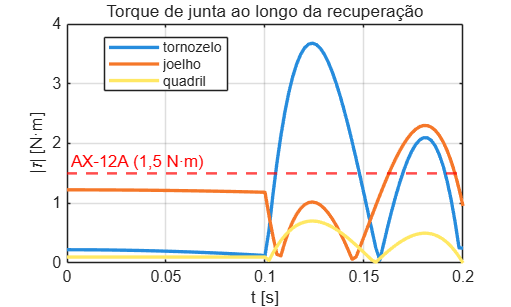


% gráfico do torque
fig_tau = figure('Color', 'w');
try, theme(fig_tau, 'light'); catch, end
hold on; grid on; box on;

cor = lines(3);
nomes_leg = {'tornozelo', 'joelho', 'quadril'};
for j = 1:3
    plot(tv, abs(TAU(j,:)), 'LineWidth', 2, 'Color', cor(j,:));
end
yline(tau_max, '--r', 'AX-12A (1,5 N·m)', 'LineWidth', 1.5, ...
      'LabelHorizontalAlignment', 'left');

xlabel('t [s]'); ylabel('|\tau| [N·m]');
legend(nomes_leg, 'Location', 'best');
title('Torque de junta ao longo da recuperação', 'FontWeight', 'normal');

### Movimento corrigido com limite de torque

Dessa forma percebe-se que um fator excencial no calculo é o tempo de correção que no momento é tratado como uma constante 0.1s. Dessa forma pode-se usar o calculo do torque para aumentar o tempo da correção até o momento em que o o torque de todos os motores estão dentro do limite de torque.

% Alonga o retorno de 0,01 s em 0,01 s: mais tempo => menos aceleração =>
% menos torque. A fase da perturbação (tv2) não depende de T_cor — ela é o
% piso da busca. Se o pico dela já passasse de tau_max, nenhum T_cor
% resolveria; daí a trava T_busca_max.

passo_T     = 0.01;    % alongamento a cada tentativa                  [s]
T_busca_max = 1.00;    % trava de segurança: aborta a busca aqui       [s]

T_cor_ok = T_cor;      % começa do valor já usado na seção anterior
achou    = false;

while ~achou && T_cor_ok <= T_busca_max
    % ── mesma quíntica de antes, agora com o T_cor da tentativa ──────────
    Cx_c = quintico_coef(pos1(1), vel1(1), acc1(1), alvo0(1), 0, 0, T_cor_ok);
    Cy_c = quintico_coef(pos1(2), vel1(2), acc1(2), alvo0(2), 0, 0, T_cor_ok);
    f3_c = Cx_c(1) + Cx_c(2)*s + Cx_c(3)*s^2 + Cx_c(4)*s^3 + Cx_c(5)*s^4 + Cx_c(6)*s^5;
    g3_c = Cy_c(1) + Cy_c(2)*s + Cy_c(3)*s^2 + Cy_c(4)*s^3 + Cy_c(5)*s^4 + Cy_c(6)*s^5;

    tv3_c = 0:P.dt:T_cor_ok;
    [Q3_c, ~, DDQ3_c] = cinematica_cm(P, s, f3_c, g3_c, tv3_c);

    % ── linha do tempo completa: perturbação + retorno ───────────────────
    tv_c  = [tv2,  t_reac + tv3_c];
    Q_c   = [Q2,   Q3_c];
    DDQ_c = [DDQ2, DDQ3_c];

    % ── mesma dinâmica inversa da seção anterior ─────────────────────────
    TAU_c = zeros(3, numel(tv_c));
    for k = 1:numel(tv_c)
        lambda_k   = (f_phi_din_q(Q_c(:,k)).') \ (QA - M*DDQ_c(:,k));
        TAU_c(:,k) = -lambda_k(7:9);
    end

    tau_pico_c = max(abs(TAU_c), [], 2);
    fprintf('T_cor = %.2f s  ->  |tau| max = [%6.3f %6.3f %6.3f] N·m\n', ...
        T_cor_ok, tau_pico_c);

    achou = all(tau_pico_c < tau_max);
    if ~achou
        T_cor_ok = T_cor_ok + passo_T;
    end
end

T_cor = 0.10 s  ->  |tau| max = [ 3.679  2.303  0.703] N·m
T_cor = 0.11 s  ->  |tau| max = [ 3.282  2.121  0.618] N·m
T_cor = 0.12 s  ->  |tau| max = [ 2.969  1.979  0.551] N·m
T_cor = 0.13 s  ->  |tau| max = [ 2.718  1.866  0.496] N·m
T_cor = 0.14 s  ->  |tau| max = [ 2.511  1.774  0.452] N·m
T_cor = 0.15 s  ->  |tau| max = [ 2.340  1.698  0.415] N·m
T_cor = 0.16 s  ->  |tau| max = [ 2.196  1.635  0.383] N·m
T_cor = 0.17 s  ->  |tau| max = [ 2.073  1.581  0.356] N·m
T_cor = 0.18 s  ->  |tau| max = [ 1.967  1.535  0.333] N·m
T_cor = 0.19 s  ->  |tau| max = [ 1.876  1.495  0.313] N·m
T_cor = 0.20 s  ->  |tau| max = [ 1.796  1.461  0.295] N·m
T_cor = 0.21 s  ->  |tau| max = [ 1.727  1.430  0.279] N·m
T_cor = 0.22 s  ->  |tau| max = [ 1.665  1.403  0.265] N·m
T_cor = 0.23 s  ->  |tau| max = [ 1.610  1.379  0.252] N·m
T_cor = 0.24 s  ->  |tau| max = [ 1.561  1.357  0.241] N·m
T_cor = 0.25 s  ->  |tau| max = [ 1.518  1.338  0.231] N·m
T_cor = 0.26 s  ->  |tau| max = [ 1.479  1.321  0.221] N


if ~achou
    error('Nenhum T_cor até %.2f s respeitou tau_max = %.2f N·m.', T_busca_max, tau_max);
end

fprintf('\nMenor tempo de correção dentro de %.2f N·m:  T_cor = %.2f s\n', tau_max, T_cor_ok);


Menor tempo de correção dentro de 1.50 N·m:  T_cor = 0.26 s


for j = 1:3
    fprintf('   %-10s %7.4f N·m\n', nomes{j}, tau_pico_c(j));
end

   tornozelo   1.4787 N·m
   joelho      1.3206 N·m
   quadril     0.2213 N·m


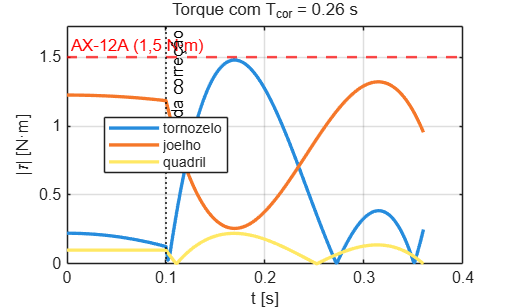


fig_ok = figure('Color', 'w');
try, theme(fig_ok, 'light'); catch, end
hold on; grid on; box on;

for j = 1:3
    plot(tv_c, abs(TAU_c(j,:)), 'LineWidth', 2, 'Color', cor(j,:));
end
yline(tau_max, '--r', 'AX-12A (1,5 N·m)', 'LineWidth', 1.5, ...
    'LabelHorizontalAlignment', 'left');
xline(t_reac, ':k', 'início da correção', 'LineWidth', 1.2);

ylim([0, 1.15*tau_max]);
xlabel('t [s]'); ylabel('|\tau| [N·m]');
legend(nomes_leg, 'Location', 'best');
title(sprintf('Torque com T_{cor} = %.2f s', T_cor_ok), 'FontWeight', 'normal');

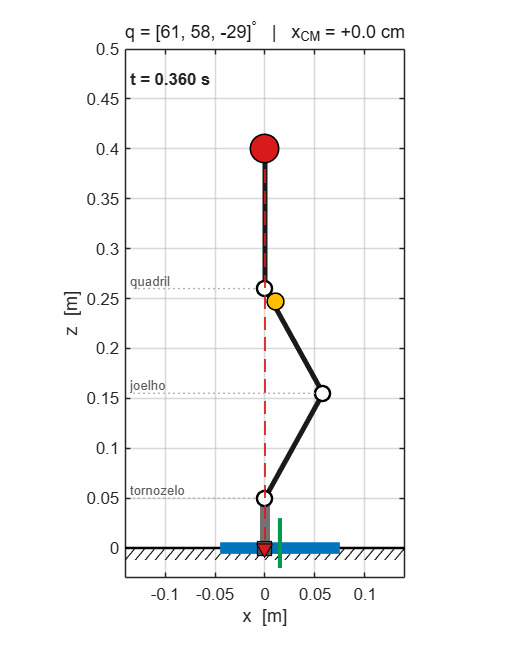

Animação salva em animacao_cm.gif (150 quadros, 4.0 s de GIF)



% animar robô
Q_junta_c = P.T_junta * Q_c([3 6 9], :);
anima_robo(P, Q_junta_c, tv_c, 'animacao_cm.gif');

## Funções

function C = quintico_coef(p0, v0, a0, pT, vT, aT, T)
%QUINTICO_COEF  Coeficientes [c0..c5] de c0+c1*s+...+c5*s^5, com posição,
%  velocidade e aceleração prescritas em s=0 e s=T.
c0 = p0;  c1 = v0;  c2 = a0/2;
A = [T^3 T^4 T^5; 3*T^2 4*T^3 5*T^4; 6*T 12*T^2 20*T^3];
b = [ pT - (c0+c1*T+c2*T^2) ;
    vT - (c1+2*c2*T)      ;
    aT - 2*c2             ];
C = [c0; c1; c2; A\b];
end

% descrição de funções

% a = simplify(a) -  (Symbolic Math Toolbox) pega uma expressão simbólica e tenta reescrevê-la numa forma algebricamente equivalente mais enxuta
%                     sin(a)*cos(b) - cos(a)*sin(b)  = sin(a-b)